# Project 2

*Authors:* Dakota Chang and Kenneth Xiong

*Last Updated: *November 4, 2023

*Summary: *This computational essay serves as the ModSim 23-24 Fall Term Project 2, focusing on the modeling query: 'How does class size influence disease spread within a student population?' Employing an agent-based model and a complete graph featuring pods of various sizes and weights, we aim to address this question. The notebook is structured into four main sections: Question, Methodology, Results, and Interpretation.

## **QUESTION**

**Modeling Question:** How does class size influence disease spread within a student population?

## METHODOLOGY

**Model:**

To best capture the dynamics of the social network within a school, we've opted for a "leaky pod" agent-based model. In this model, each pod corresponds to a specific class. The strength of connections between individual agents within a pod is determined by class size, with smaller classes resulting in more robust connections. We've chosen to represent this relationship using a ratio of ####. 

Additionally, our model is designed as a complete graph to simulate the comprehensive interconnections characteristic of a school's social network. However, it's important to note that these connections are intentionally configured to be relatively weak in nature.

**Assumptions:**

We hypothesize that smaller class sizes foster stronger connections among students within a particular class. This hypothesis is grounded in the observation that larger classes typically adopt a lecture-based format in extensive lecture halls, whereas smaller classes often emphasize interactive and team-based learning. These assumptions are reasonable within the context of our model, which investigates the impact of class sizes and teaching styles on disease transmission. 

We also assume complete interconnectedness among all students might not hold true in larger colleges. Moreover, we've assumed equal connectivity among students within each class. Nevertheless, these specific assumptions might not be directly pertinent to our primary modeling objective, which primarily focuses on the effects of class size and teaching methodologies on disease spread rather than providing a precise estimation of disease transmission rates.

Demonstration of function "create_classes."

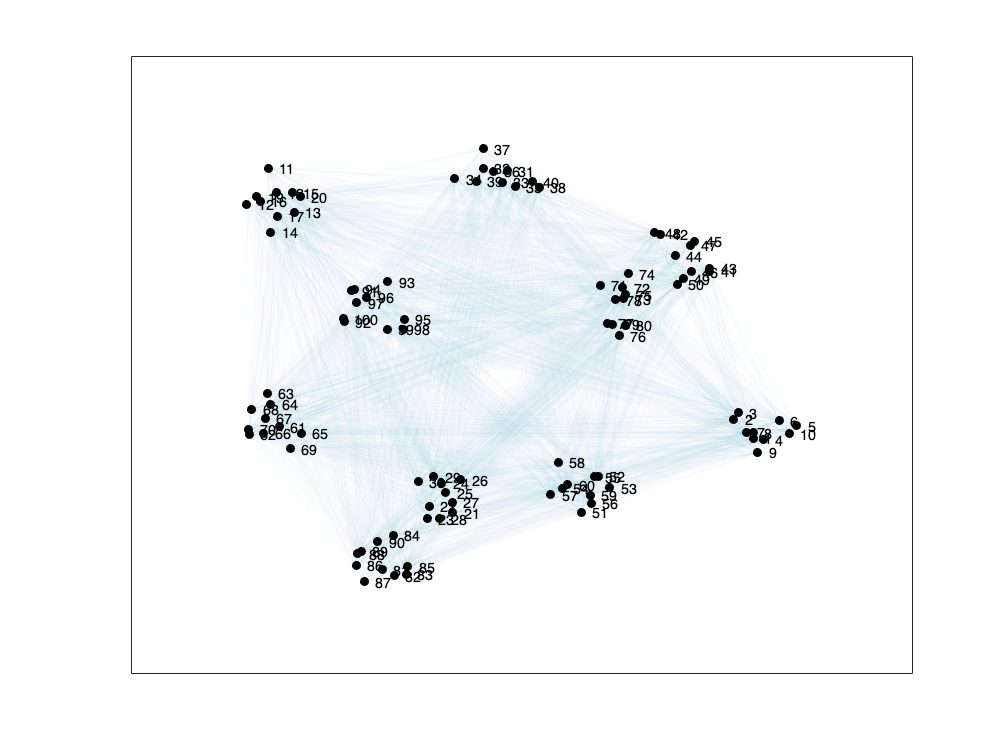

total_pop = 100; 
class_size = 10;
weight = total_pop/class_size;
create_classes(total_pop, class_size, weight);

Here is the code to conduct three distinct simulations across 150 time steps. One simulation focuses on small class sizes, assuming 10 students per class. The second simulation involves medium class sizes, with an assumed count of 50 students per class. The third simulation pertains to large class sizes, where an assumed count of 100 students per class is utilized. The total school population is set at 1000 individuals. As previously highlighted, these assumptions are designed not to significantly impact the ultimate results, as our primary aim is to observe trends rather than precisely predict disease spread rates.

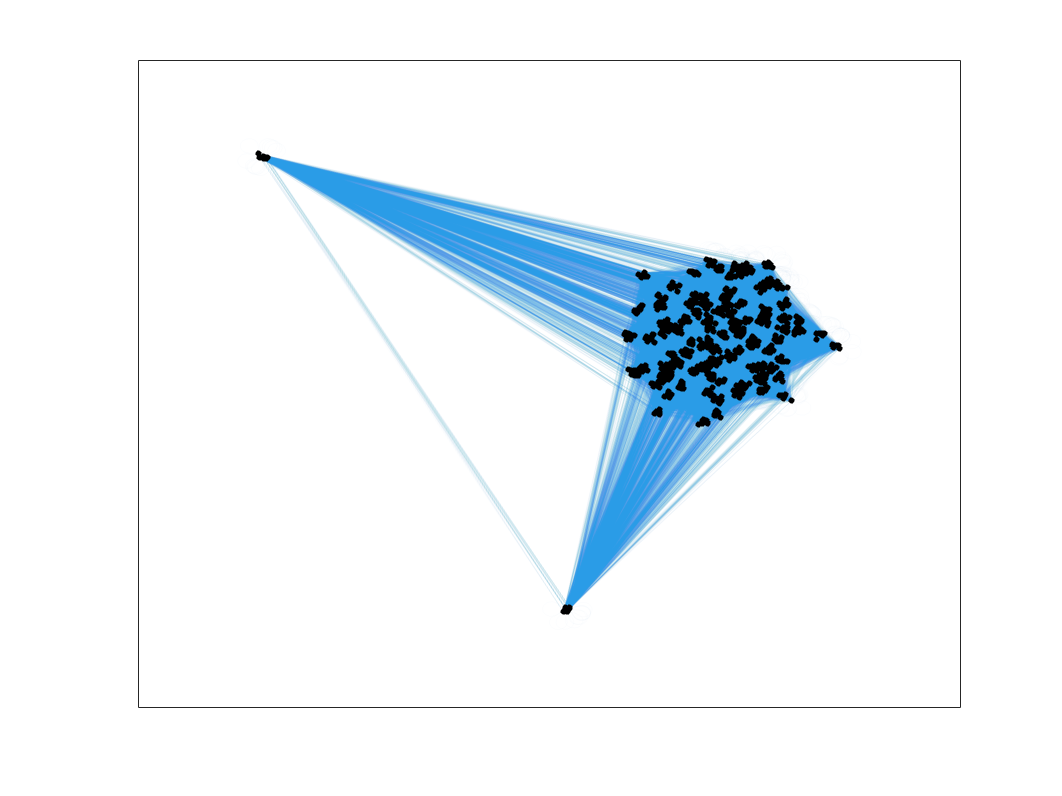

total_pop = 1000;

% creates complete graph overlaid by leaky pod graph to calibrate connection weights 
[M_small, plot_small] = create_classes(total_pop , 10, total_pop /10); % small class

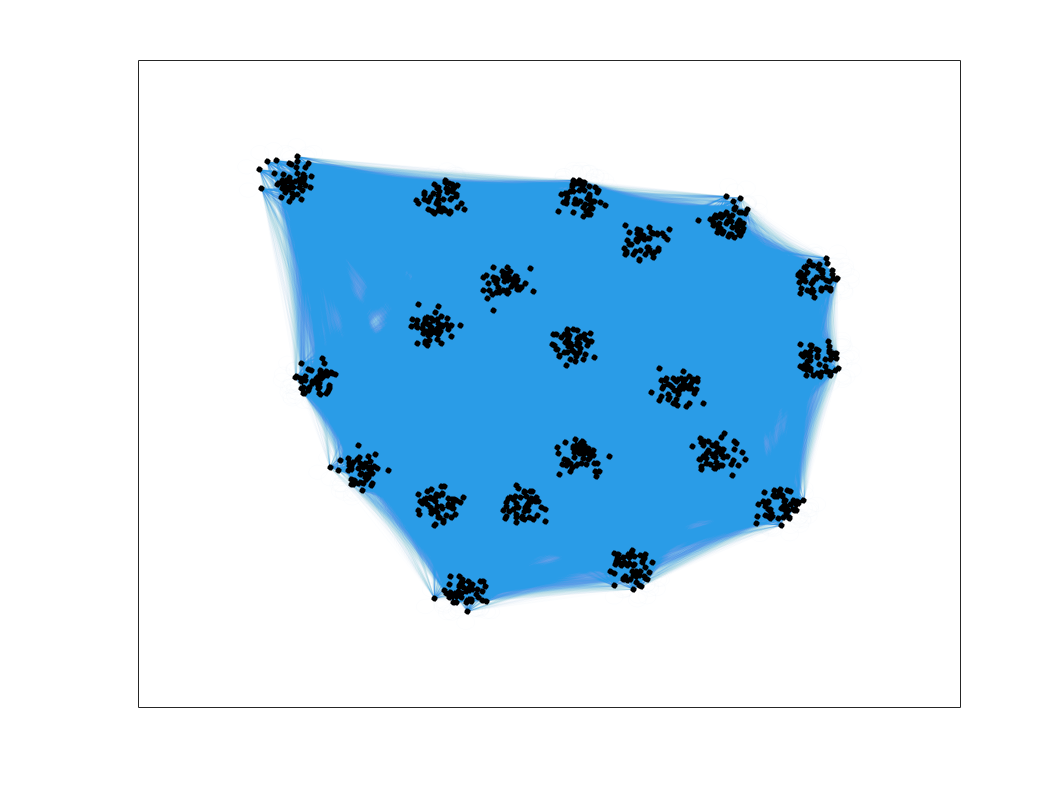

[M_medium, plot_medium] = create_classes(total_pop , 50, total_pop /50); % medium class

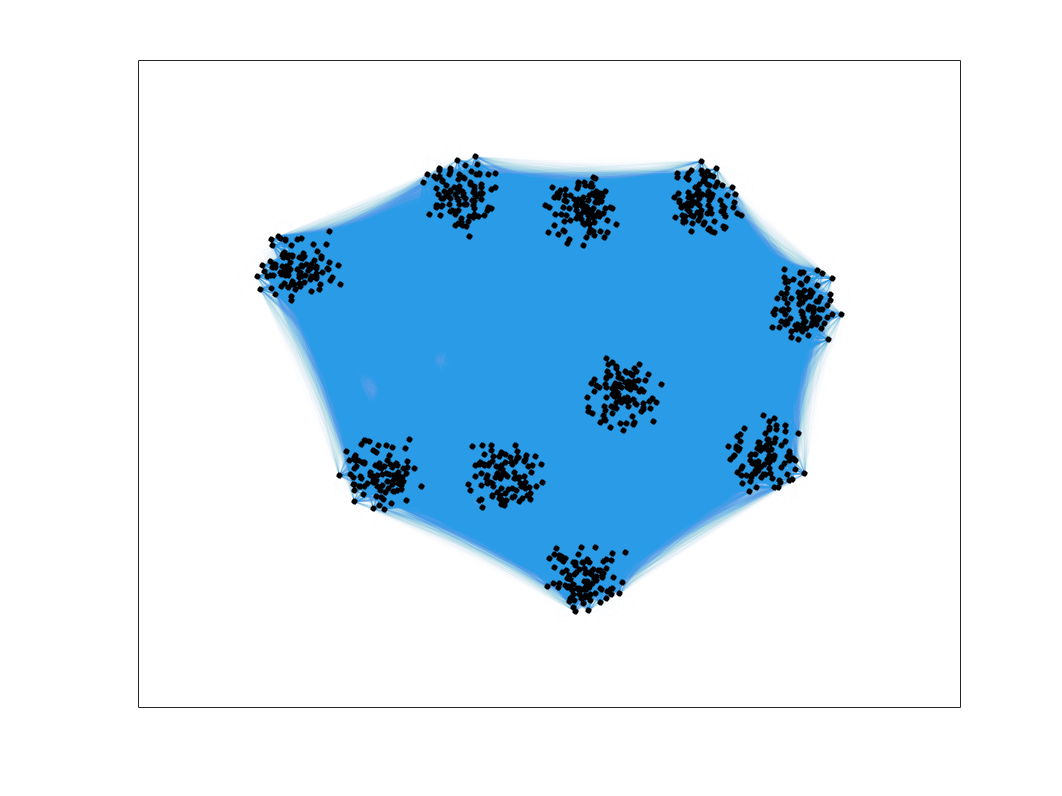

[M_big, plot_big] = create_classes(total_pop , 100, total_pop /100); % big class

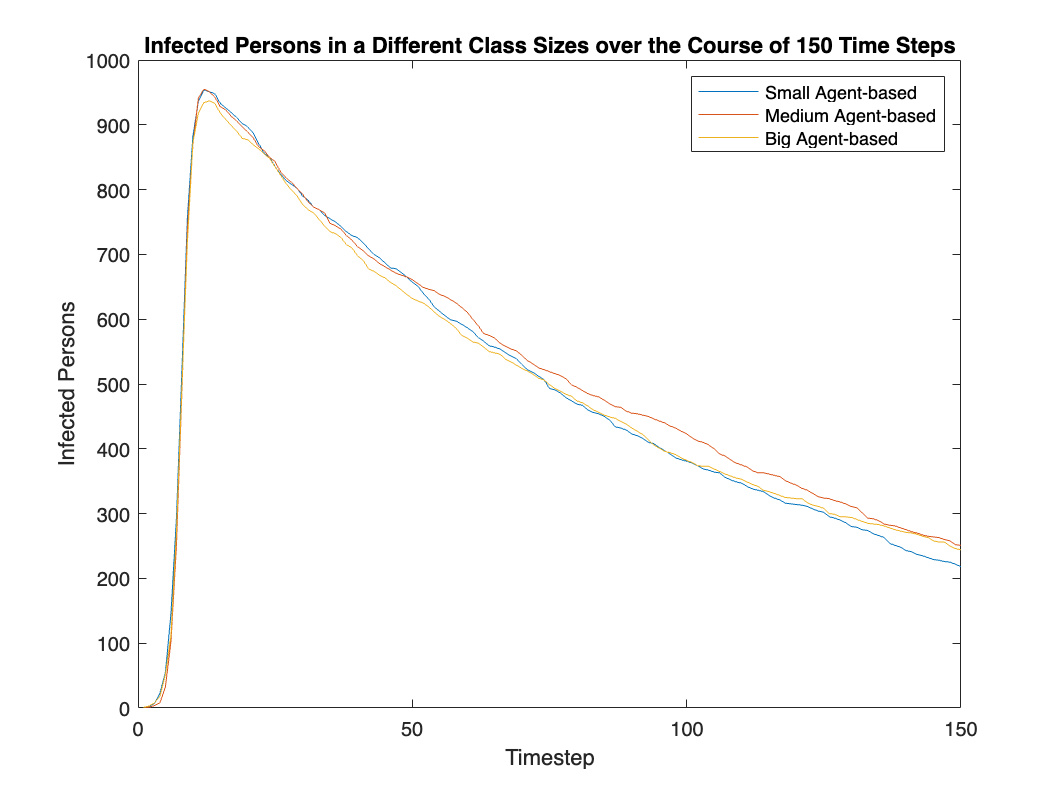


% matrix of same size to store infected persons per time step,
% matrix starts with one as we assume one student to be patient #0.
Iv1 = zeros(total_pop , 1);
Iv1(1) = 1;

% infection and recovery rate
infection_rate = 0.001; recovery_rate = 0.01;

% simulation of disease spread in constructed models
[Ss, Is, Rs] = simulate_absir(M_small, Iv1, 150, infection_rate, recovery_rate);
[Sm, Im, Rm] = simulate_absir(M_medium, Iv1, 150, infection_rate, recovery_rate);
[Sb, Ib, Rb] = simulate_absir(M_big, Iv1, 150, infection_rate, recovery_rate);

Is_count = sum(Is, 1);
Im_count = sum(Im, 1);
Ib_count = sum(Ib, 1);

% Visualize
figure()
plot(Is_count, 'DisplayName', 'Small Agent-based'); hold on;
plot(Im_count, 'DisplayName', 'Medium Agent-based');
plot(Ib_count, 'DisplayName', 'Big Agent-based');
legend()
title("Infected Persons in a Different Class Sizes over the Course of 150 Time Steps")
xlabel('Timestep')
ylabel('Infected Persons')

*TODO:*

*Development*

- How did you set the parameters of your model?

- What verification facts did you come up with for your model? What assert() statements did you use to implement your verification facts?

- Your assert() statements must appear in your computational essay

Parameter Sweep (Infection Rate)

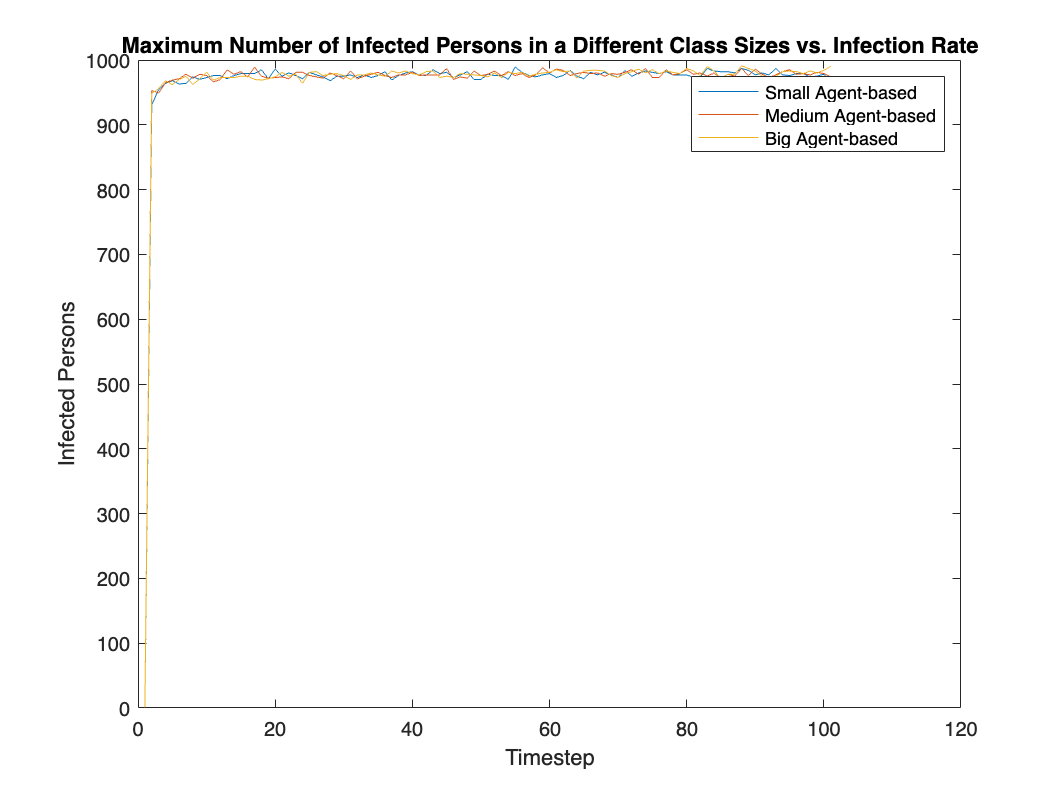

% parameter sweep for infection rate:
infection_rate = 0:0.001:0.1;
recovery_rate = 0.01;
Is_peak = zeros(1, 100); Im_peak = zeros(1, 100); Ib_peak = zeros(1, 100);

for i = 1 : length(infection_rate)
    [Ss, Is, Rs] = simulate_absir(M_small, Iv1, 150, infection_rate(i), recovery_rate);
    [Sm, Im, Rm] = simulate_absir(M_medium, Iv1, 150, infection_rate(i), recovery_rate);
    [Sb, Ib, Rb] = simulate_absir(M_big, Iv1, 150, infection_rate(i), recovery_rate);
    
    Is_peak(i) = max(sum(Is));
    Im_peak(i) = max(sum(Im));
    Ib_peak(i) = max(sum(Ib));
end

figure()
plot(Is_peak, 'DisplayName', 'Small Agent-based'); hold on;
plot(Im_peak, 'DisplayName', 'Medium Agent-based');
plot(Ib_peak, 'DisplayName', 'Big Agent-based');
legend()
title("Maximum Number of Infected Persons in a Different Class Sizes vs. Infection Rate")
xlabel('Timestep')
ylabel('Infected Persons')

Parameter Sweep (Recovery Rate)

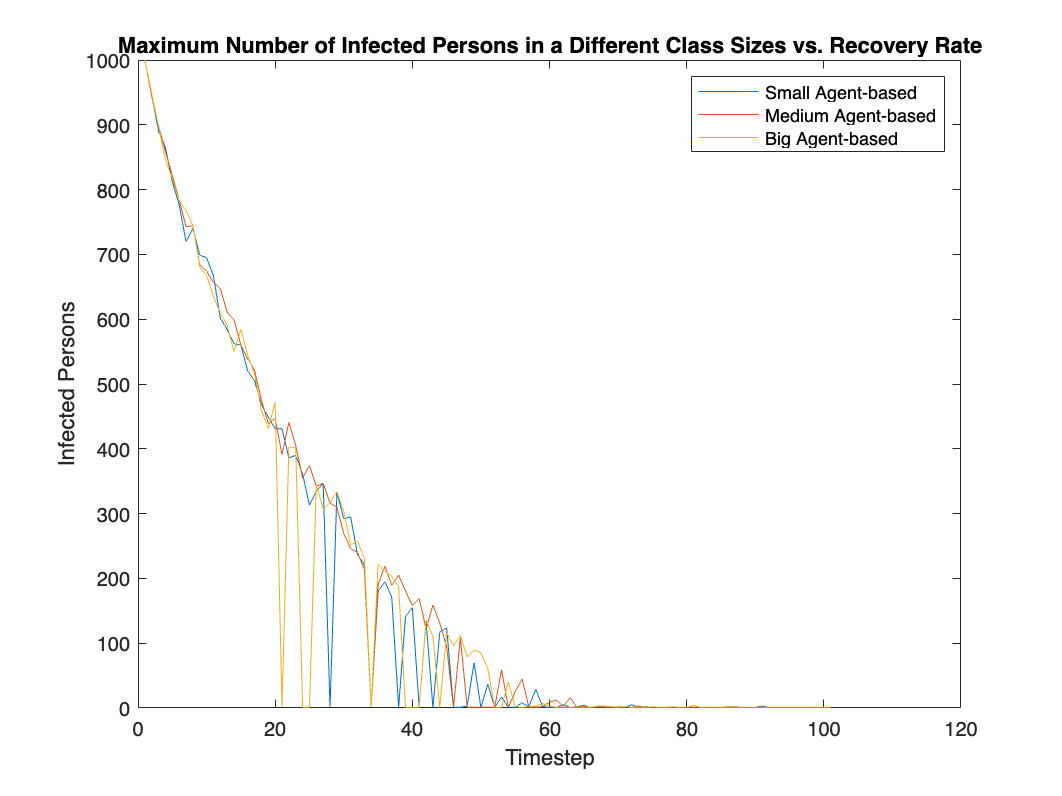

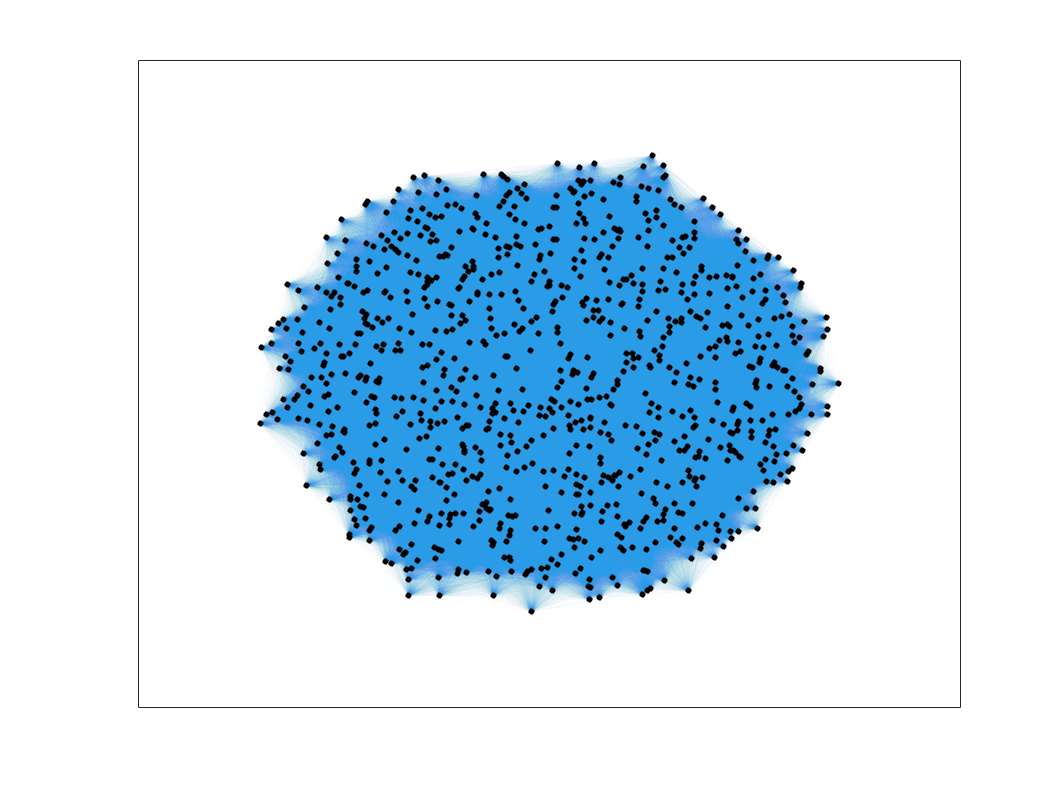

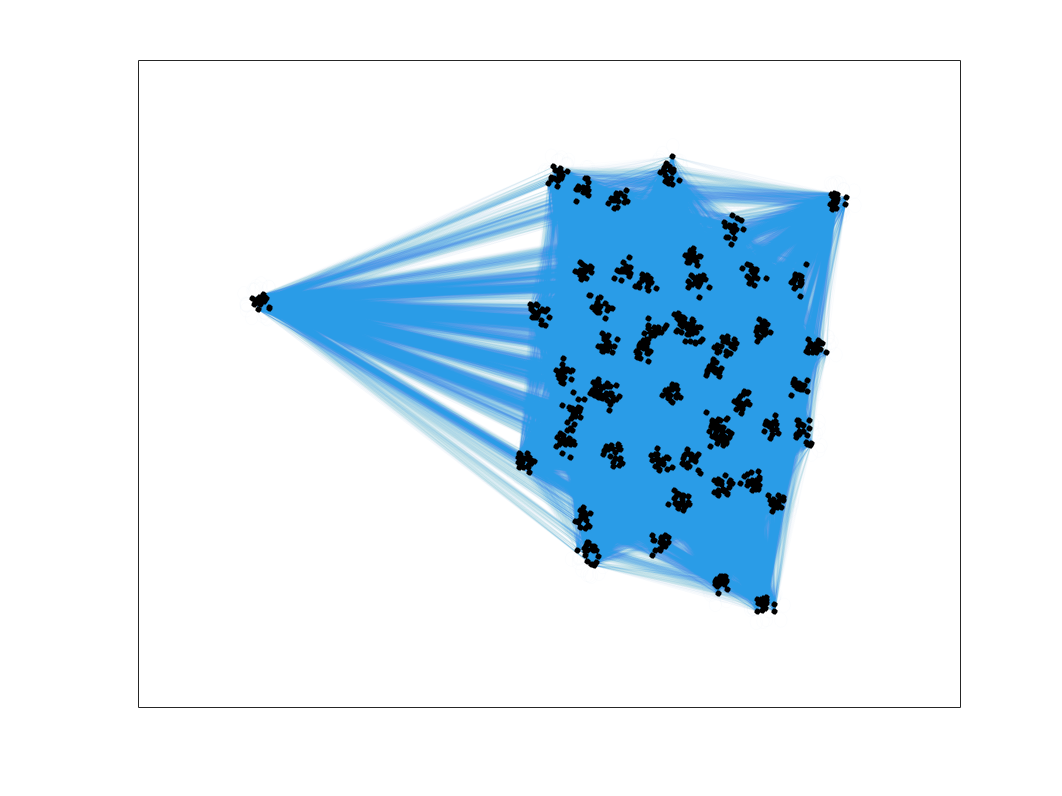

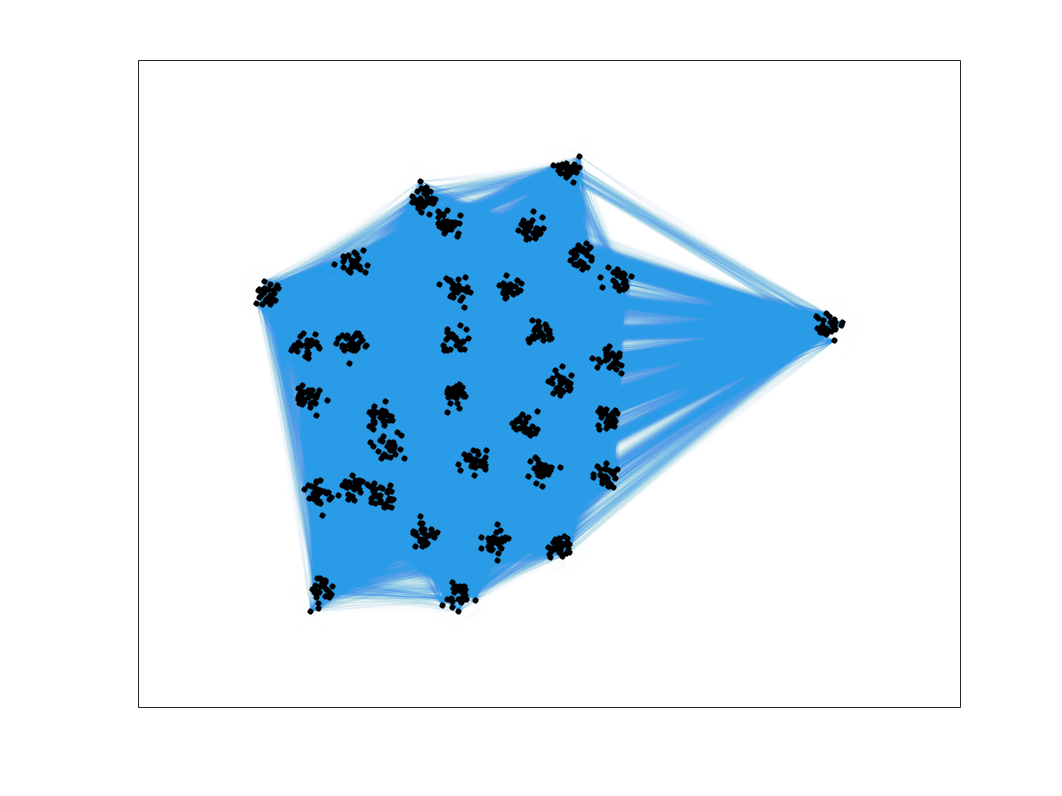

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To operate on each element of the matrix individually, use TIMES (.*) for elementwise multiplication.

Error in simulate_absir/action (line 30)
        v_eff = infection_rate * M * I;

Error in simulate_absir (

% parameter sweep for recovery rate:
infection_rate = 0.001;
recovery_rate = 0:0.01:1;
Is_peak = zeros(1, 100); Im_peak = zeros(1, 100); Ib_peak = zeros(1, 100);

for i = 1 : length(recovery_rate)
    [Ss, Is, Rs] = simulate_absir(M_small, Iv1, 150, infection_rate, recovery_rate(i));
    [Sm, Im, Rm] = simulate_absir(M_medium, Iv1, 150, infection_rate, recovery_rate(i));
    [Sb, Ib, Rb] = simulate_absir(M_big, Iv1, 150, infection_rate, recovery_rate(i));
    
    Is_peak(i) = max(sum(Is));
    Im_peak(i) = max(sum(Im));
    Ib_peak(i) = max(sum(Ib));
end

figure()
plot(Is_peak, 'DisplayName', 'Small Agent-based'); hold on;
plot(Im_peak, 'DisplayName', 'Medium Agent-based');
plot(Ib_peak, 'DisplayName', 'Big Agent-based');
legend()
title("Maximum Number of Infected Persons in a Different Class Sizes vs. Recovery Rate")
xlabel('Timestep')
ylabel('Infected Persons')

## Results

% Example matrix
A = [1 2 3; 4 5 6; 7 8 9];

    12    15    18




% Finding the sum of each column
columnSums = sum(A); % This sums each column

% Display the sums of each column
disp(columnSums);


## Interpretation